fname = 'Pilot10_results.json';
fid = fopen(fname);
raw = fread(fid,inf);
str = char(raw');
fclose(fid);
result = jsondecode(str);

for j = 1:length(result.Batches)
    for i = 1:length(result.Batches(j).Trials)
        trialNumber = result.Batches(j).Trials(i).TrialNumber;
        DisplayTarget = result.Batches(j).Trials(i).DisplayTarget;
        video = result.Batches(j).Trials(i).Video;
        mouseResponse = result.Batches(j).Trials(i).Response.MouseResponse;
        responseTime = result.Batches(j).Trials(i).Response.ResponseTime;
        disp(j + ", " + trialNumber + ", " + DisplayTarget + ", " + video + ", " + mouseResponse + ", " + responseTime)
    end
end

1, 1, AR, beep_video14, 1, 9.7063
1, 2, AR, beep_video4, 1, 2.0771
1, 3, AR, beep_video10, 1, 2.5635
1, 4, AR, beep_video7, 0, 8.9476
1, 5, AR, beep_video5, 1, 4.6342
1, 6, AR, beep_video7, 1, 2.0835
1, 7, AR, beep_video6, 1, 1.9723
1, 8, AR, beep_video6, 0, 5.2999
1, 9, AR, beep_video9, 1, 1.8338
1, 10, AR, beep_video9, 0, 1.6172
1, 11, AR, beep_video8, 1, 1.9925
1, 12, AR, beep_video11, 1, 2.9652
1, 13, AR, beep_video13, 1, 1.9568
1, 14, AR, beep_video6, 0, 1.5369
1, 15, AR, beep_video10, 1, 1.661
1, 16, AR, beep_video14, 1, 2.2998
1, 17, AR, beep_video5, 1, 3.7335
1, 18, AR, beep_video7, 1, 2.0343
1, 19, AR, beep_video14, 1, 2.1031
1, 20, AR, beep_video13, 1, 2.2449
1, 21, AR, beep_video14, 0, 3.3529
1, 22, AR, beep_video6, 1, 1.8734
1, 23, AR, beep_video10, 0, 2.114
1, 24, AR, beep_video13, 0, 2.9803
1, 25, AR, beep_video4, 1, 1.7434
1, 26, AR, beep_video12, 0, 2.6821
1, 27, AR, beep_video12, 0, 2.1478
1, 28, AR, beep_video5, 1, 2.1947
2, 1, AR, violin_video9, 1, 6.3213
2, 2, AR, v

HistResults = zeros(11,2,3);


participant = 3;
%beep
for j = [1,3]
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 3;
        

        if (response == 0)
            HistResults(videoNumber, 1, participant) = HistResults(videoNumber, 1, participant) + 1;
        end
    end
end
%violin
for j = [2,4]
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 3;
        
        if (response == 0)
            HistResults(videoNumber, 2, participant) = HistResults(videoNumber, 2, participant) + 1;
        end
    end
end

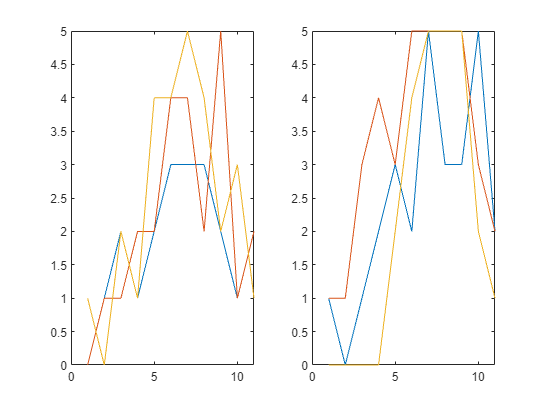

subplot(1,2,1); hold off; plot(HistResults(:,1,1)); hold on; plot(HistResults(:,1,2)); plot(HistResults(:,1,3))
subplot(1,2,2); plot(HistResults(:,2,1)); hold on; plot(HistResults(:,2,2)); plot(HistResults(:,2,3)); hold off;